# Radar Signal Processing - Attacks

Creating this script to study the effect of different attacks on the radar signal processing

## Initialize the simulator

clear;
simulator = Simulator_revA();
%setup the victim's chirp parameters

simulator.load_B210_victim_params;
simulator.load_B210_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 64
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.20 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 0.61 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us
	 Samples per chirp 		 2926.00 


## Initialize the Target Emulator

target_range = 70; %m
target_velocity = 15; % m/s
emulated_target = FMCW_Emulator_revA(simulator.Victim,target_range,target_velocity,"target");

## Initialize an emulated Attacker

attack_range = 70; %m
attack_velocity = 15; % m/s
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"velocity spoof - similar velocity");
 emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"velocity spoof - noisy");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"range spoof - similar slope");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,...
%     "range spoof - similar slope,velocity spoof - noisy");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,...
%     "range spoof - similar slope,velocity spoof - similar velocity");

Writing code to simulate the signal propogation through the signal processing chain

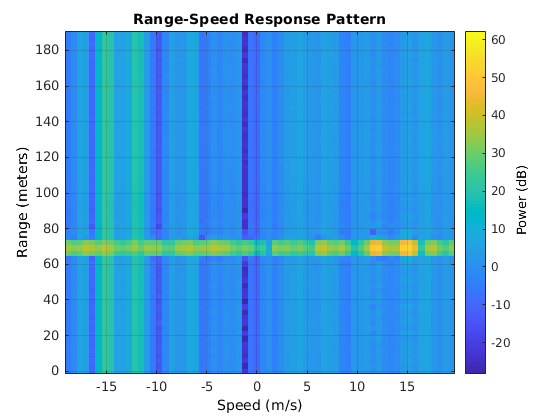

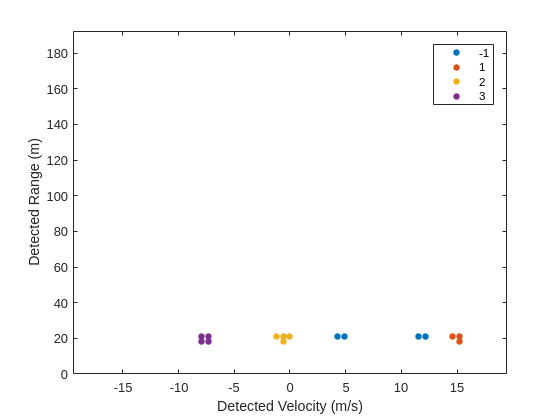

%specify the number of frames and chirps to compute
frames_to_compute = 100;
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
emulated_target.reset_emulated_chirp_computation();
emulated_attacker.reset_emulated_chirp_computation();
simulator.Victim.precompute_radar_chirps();


%configure things to be able to generate a movie
figure
axis fill
F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);


for frame = int32(1:frames_to_compute)
    
    %compute the emulated chirps for the current frame
    emulated_target.compute_next_emulated_chirps();

    %compute the emulated attack chirps for the current frame
    emulated_attacker.compute_next_emulated_chirps();

    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        %Rx_sig = emulated_target.emulated_chirps(:,chirp);
        Rx_sig = emulated_attacker.emulated_chirps(:,chirp) + emulated_target.emulated_chirps(:,chirp);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %plot the doppler response and save it for a movie
    plotResponse(simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse,radar_cube);
    drawnow
    F_rngdop(frame) = getframe(gcf);
    
    %CA CFAR 2-D
    detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    %DBSCAN Clustering
    if ~isempty(detections)
        idx = dbscan(detections.',simulator.Victim.Radar_Signal_Processor.Epsilon,simulator.Victim.Radar_Signal_Processor.minpts);
        
        %estimate the range and the velocities
        rngest = simulator.Victim.Radar_Signal_Processor.RangeEstimator(resp,rnggrid,detections,idx.');
        dopest = simulator.Victim.Radar_Signal_Processor.DopplerEstimator(resp,dopgrid,detections,idx.');
    else
        idx = [];
        rngest = nan(simulator.Victim.Radar_Signal_Processor.NumEstimates_rng,1);
        dopest = nan(simulator.Victim.Radar_Signal_Processor.NumEstimates_dplr,1);
    end
    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx,[],[],[],'on',"Detected Velocity (m/s)","Detected Range (m)");
    axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
    drawnow
    F_clusters(frame) = getframe(gcf);

    
end

%play the movie for the range doppler
clf;
fig = figure;
movie(fig,F_rngdop,1,10)

%play the movie for the clusters
fig = figure;
movie(fig,F_clusters,1,10)

Generate a subplot sampling of multiple frames for a preview of the movie

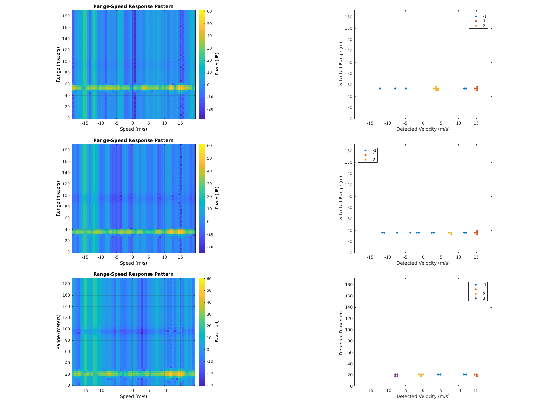

clf;
figure;
axis fill;
tiledlayout(3,2,TileSpacing="none",Padding="tight")
for i = 1:3
    %subplot of the Doppler in the left column
    nexttile
    [X,map] = frame2im(F_rngdop(ceil((i/3)*frames_to_compute)));
    imshow(X,map)
    %subplot of the clustering in the right column
    nexttile
    [X,map] = frame2im(F_clusters(ceil((i/3)*frames_to_compute)));
    imshow(X,map)
end